# Robust Control

clc 
clear all
close all 
DuCy=20; 
Io=5; Vo=5;
Vg=24; Vd=0;

Vs=[Vg Vd];
X=[Io Vo];

[A,B,C,D,G] =flyback_ss(Vs,X,DuCy)

A = 	1.0e+07 *

   -0.0400   -7.6000
    0.0380   -0.0000


B =    -40000000    76000000
           0           0


C =      0     1


D =      0     0


G =
 
                                        
  1e05 s^3 - 2.58e13 s^2 - 7.447e18 s   
                                        
                              - 7.462e26
                                        
  --------------------------------------
                                        
  s^4 + 8e05 s^3 + 5.792e13 s^2         
                                        
                  + 2.31e19 s + 8.341e26
                                        
 
Continuous-time transfer function.




% Create the state-space model
sys = ss(A, B, C, D);

**Modeling Plant Variability as Uncertainty**

Pnom = tf(2,[1 -2]);

p1 = Pnom*tf(1,[.06 1]);              % extra lag
p2 = Pnom*tf([-.02 1],[.02 1]);       % time delay
p3 = Pnom*tf(50^2,[1 2*.1*50 50^2]);  % high frequency resonance
p4 = tf(2.4,[1 -2.2]);                % pole/gain migration

To apply robust control tools, we can replace this set of models with a single uncertain plant model whose range of behaviors includes `p1` through `p6`. This is one use of the command `ucover`. This command takes an array of LTI models `Parray` and a nominal model `Pnom` and models the difference `Parray-Pnom` as multiplicative uncertainty in the system dynamics.

Because `ucover` expects an array of models, use the `stack` command to gather the plant models `p1` through `p6` into one array.

Parray = stack(1,p1,p2,p3,p4);

Next, use `ucover` to "cover" the range of behaviors `Parray` with an uncertain model of the form

`P = Pnom * (1 + Wt * Delta)`

where all uncertainty is concentrated in the "unmodeled dynamics" `Delta` (a `ultidyn` object). Because the gain of `Delta` is uniformly bounded by 1 at all frequencies, a "shaping" filter `Wt` is used to capture how the relative amount of uncertainty varies with frequency. This filter is also referred to as the uncertainty weighting function.

Try a 4th-order filter `Wt` for this example:

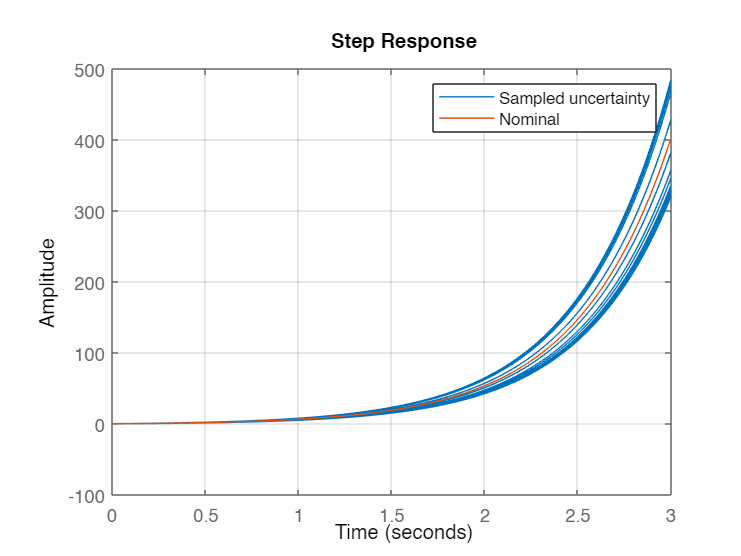

orderWt = 4;
Parrayg = frd(Parray,logspace(-1,3,60));
[P,Info] = ucover(Parrayg,Pnom,orderWt,'InputMult');
step(P,getNominal(P),3)
grid on
legend('Sampled uncertainty','Nominal')

The target control bandwidth is 10 rad/s. Create a tunable PID controller and fix its derivative filter time constant to  (10 times the bandwidth) so that there are only three gains to tune (proportional, integral, and derivative gains).

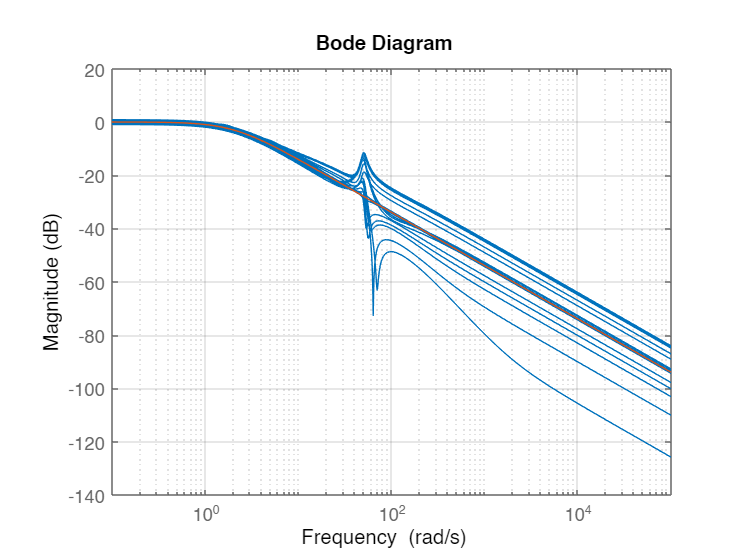

bodemag(P,getNominal(P))
grid on

C = tunablePID2('C','pid');
C.Tf.Value = 0.01;  C.Tf.Free = false;  % fix Tf=0.01

Construct a tunable model `T0` of the closed-loop transfer from `r` to `y`. Use an "analysis point" block to mark the location `u` where the disturbance enters.

AP = AnalysisPoint('u');
CL0 = feedback(P*AP*C,1,2,1,+1);
CL0 = CL0(:,1);
CL0.u = 'r';  CL0.y = 'y';

The gain of the open-loop response  is a key indicator of the feedback loop behavior. The open-loop gain should be high (greater than one) inside the control bandwidth to ensure good disturbance rejection, and should be low (less than one) outside the control bandwidth to be insensitive to measurement noise and unmodeled plant dynamics. Accordingly, use three requirements to express the control objectives:

- "Tracking" requirement to specify a response time of about 0.2 seconds to step changes in `r`

- "MaxLoopGain" requirement to force a roll-off of -20 dB/decade past the crossover frequency 10 rad/s

- "MinLoopGain" requirement to adjust the integral gain at frequencies below 0.1 rad/s.

s = tf('s');
wc = 10; % target crossover frequency

% Tracking
R1 = TuningGoal.Tracking('r','y',2/wc);

% Bandwidth and roll-off
R2 = TuningGoal.MaxLoopGain('u',wc/s);

% Disturbance rejection
R3 = TuningGoal.MinLoopGain('u',wc/s);
R3.Focus = [0 0.1];

opt = systuneOptions('RandomStart',10);
rng(0), [CL,fSoft] = systune(CL0,R1,[R2 R3],opt);

Final: Soft = 1.36, Hard = 0.9999, Iterations = 248
Final: Soft = 1.36, Hard = 0.99987, Iterations = 123
Final: Soft = 1.36, Hard = 0.99996, Iterations = 219
Final: Soft = 1.36, Hard = 0.99975, Iterations = 139
Final: Soft = 1.36, Hard = 0.99988, Iterations = 180
Final: Soft = 1.36, Hard = 0.99963, Iterations = 182
Final: Soft = 1.36, Hard = 0.99991, Iterations = 242
Final: Soft = 1.36, Hard = 0.99979, Iterations = 147
Final: Soft = 1.36, Hard = 0.99981, Iterations = 163
Final: Soft = 1.36, Hard = 0.99987, Iterations = 185
Final: Soft = 1, Hard = 0.89246, Iterations = 109


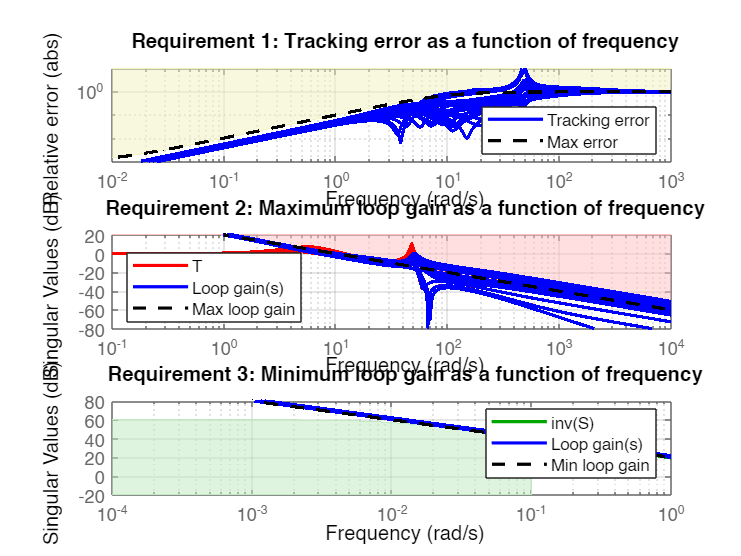

showTunable(CL)
figure
viewGoal([R1 R2 R3],CL)

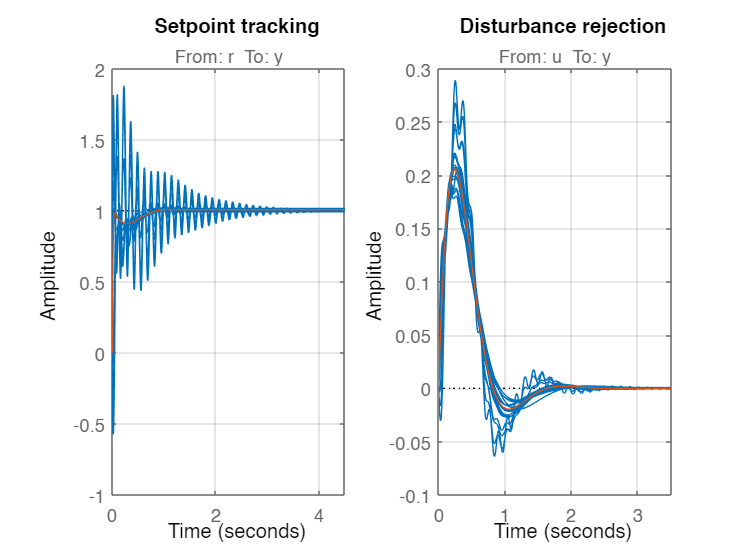

figure
subplot(1,2,1)
step(CL,getNominal(CL))
grid on
title('Setpoint tracking')
D = getIOTransfer(CL,'u','y');
subplot(1,2,2)
step(D,getNominal(D))
grid on
title('Disturbance rejection')